clear
clc
close all

# Q3

Load data

addpath('./Data')
addpath('./Models')

load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                     % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix

% Load transfer funktion for residual
load res_tf.mat

% Load data
load ECP502Data.mat


## Construct new residual

## Simulation

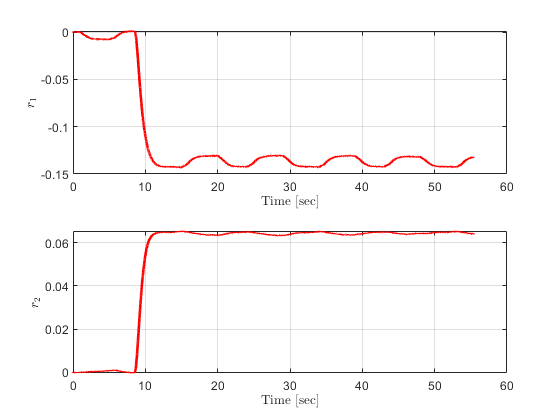

U = [t, y_meas, u_1, u_2];

SIM_TIME = t(end);
STEP_SIZE = T_s/4;

% Simulation
out = sim('q3_TDO.slx', t(end), [], U);

% % Residuals
r = out.r.Data;
r1 = r(:,1);
r2 = r(:,2);
t_d = out.r.Time;


figure(1)
subplot(2,1,1)
plot(t_d, r1, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_1$', "interpreter", "latex")

subplot(2,1,2)
plot(t_d, r2, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_2$', "interpreter", "latex")

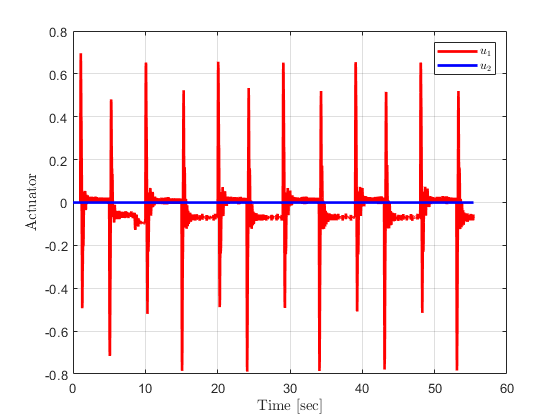


figure(2)
plot(t, u_1, 'r', 'LineWidth', 2)
hold on
plot(t, u_2, 'b', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('Actuator', "interpreter", "latex")
legend('$u_1$', '$u_2$', "interpreter", "latex")

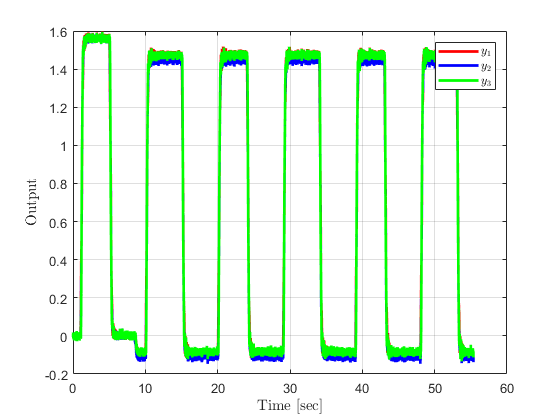



figure(3)
plot(t, y_meas(:,1), 'r', 'LineWidth', 2)
hold on
plot(t, y_meas(:,2), 'b', 'LineWidth', 2)
plot(t, y_meas(:,3), 'g', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('Output', "interpreter", "latex")
legend('$y_1$', '$y_2$', '$y_3$', "interpreter", "latex")

## Question 2


$$\begin{array}{l}
r_1 :\;0=\left(J_2 s^2 +b_2 s+\left(k_1 +k_2 \right)\right)y_2 -k_1 y_1 -k_2 y_3 -u_2 \\
r_2 :\;0=\left(J_3 s^2 +k_2 b_3 s+k_2 \right)y_3 -k_2 y_2 
\end{array}$$


Residual 2 does not have $y_1$ so this does not have a fault.

r3_tf = tf(-k_2, [J_2, b_2, k_1+k_2]);
r3_tf_d = c2d(r3_tf,T_s,'tustin');

r4_tf = tf(-k_2, [J_3, b_3, k_2]);
r4_tf_d = c2d(r4_tf, T_s,'tustin');

save r3r4.mat r4_tf_d r3_tf_d

% Simulation
out = sim('q3_TDO_v2.slx', t(end), [], U);


% % Residuals
r = out.r.Data;
r1 = r(:,1);
r2 = r(:,2);
r3 = r(:,3);
r4 = r(:,4);
t_d = out.r.Time;


figure(4)
subplot(2,1,1)
plot(t_d, r1, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_1$', "interpreter", "latex")

subplot(2,1,2)
plot(t_d, r2, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_2$', "interpreter", "latex")

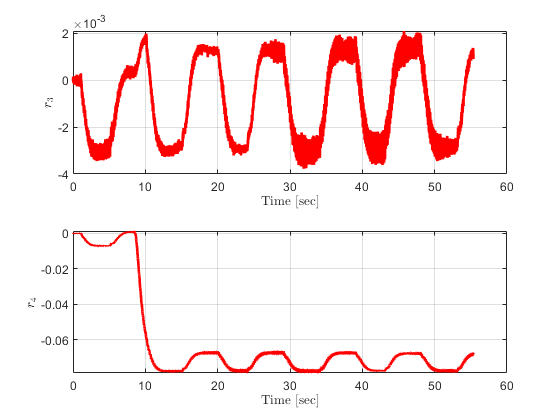


figure(5)
subplot(2,1,1)
plot(t_d, r3, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_3$', "interpreter", "latex")

subplot(2,1,2)
plot(t_d, r4, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_4$', "interpreter", "latex")

Fault on y2! (see maple)